# Simple Statistical Mechanical Model

In this section, we consider an ideal gas of point particles where each particle is an aggregate of monomers.  Using statistical mechanical considerations, we can find an expression for the most probable set of mass fractions by constrained nonlinear optimization:


$$\left\{f_k\right\}^* = \max_{\{ f_k\}}\left[-\beta \sum_k\frac{f_k\Delta g_k}{k} + \sum_k\frac{f_k}{k}\ln\left( \frac{k^{5/2}e^{5/2}}{f_k \rho \Lambda_1^3}\right) \right],$$


where $f_k$ is the mass fraction of aggregates comprised of *k* monomers, $\Delta g_k$is the free energy of the formation of a *k*-mer from isolated monomers, $\rho$ is the number density in solution, $\beta$ is the usual inverse temperature, and $\Lambda_1$ is the de Broglie wavelength of a monomer.

## Compare changing dimer free energy

% inputs

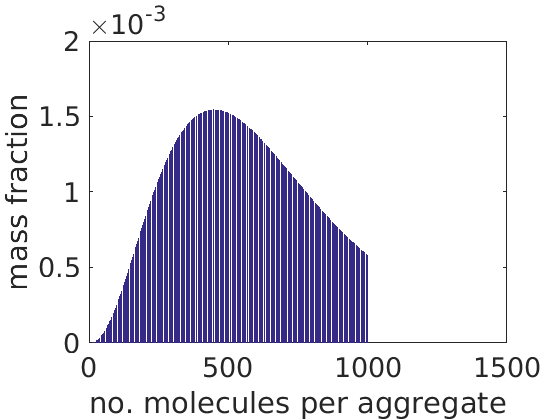

m_mon = 1151.2;                              % molecular weight of single molecule / Da
density = 4.4;                               % millimoles / Liter
Na = 6.0221409e23;                           % Avogadro's number
numberDensity = density * Na / (10^(-3));    % molecule number density / molecules/m^3

T=298;                                      % temperature / K
T_ref=298;                                  % reference temperature for at which dg_vec values are reported in units of kB*T_ref 

dg_vec = [];                                % free energy of formation of a cluster of size k from isolated monomers in ascending size order dg_vec(1) = free energy of formation of a 1-mer = 0, dg_vec(2) = free energy of formation of a 2-mer, ... / kBT @ T_ref

k_max = 1000;                % maximum cluster size to consider
dg1plus1 = -14.5; %-14.5;   % measured free energy of dimerization 1+1->2
dgnplus1 = -25.0; %-25.0;   % measured free energy of multimerization n+1->(n+1)
for k=1:k_max
    if k==1
        dg_vec(k) = 0;  % by definition
    else
        dg_vec(k) = dg1plus1 + (k-2)*dgnplus1;
    end
end


% processing inputs
k_max = length(dg_vec);                     % maximum aggregate size

rho = numberDensity;                  % molecule number density / molecules/m^3 
l=(rho)^(-1/3);                             % mean distance between uniformly dispersed monomers / m

h=6.626070040E-34;                          % Planck's constant / J.s
kB=1.38064852E-23;                          % Boltzmann's constant / J/K
Da2kg=1.660539040E-27;                      % kg per Da
Lambda_1 = h / sqrt(2*pi*m_mon*Da2kg*kB*T); % thermal de Broglie wavelength of single isolated molecule / m 


% solving for maximum term in partition function in thermodynamic limit as a function of the weight fractions of each aggregate  
% solving by direct constrained nonlinear optimization

A = [];
b = [];
Aeq = ones(1,k_max);
beq = [1];
lb = zeros(1,k_max);
ub = ones(1,k_max);
nonlcon = [];
x0 = ones(1,k_max);
options_fmincon = optimoptions('fmincon','Display','notify-detailed','OptimalityTolerance',1E-6,'ConstraintTolerance',1E-6,'StepTolerance',1E-10,'MaxFunctionEvaluations',1E6,'SpecifyObjectiveGradient',true);
[x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
figure()
bar([1:1:k_max],x);
xlabel('no. molecules per aggregate','fontsize',20);
ylabel('mass fraction','fontsize',20);
%xlim([0 find(x~=0)])
set(gca,'fontsize',20);
set(gcf,'color','w');

## Parameter Scan -- 1000 bins

tic
dg1plus1s = -1*(0.5:7:70.5);
dgnplus1s = -1*(5:5:75);
g1l = length(dg1plus1s);
gnl = length(dgnplus1s);
mouts = zeros(g1l*gnl,6);
outputs = {};
douts = zeros(g1l*gnl,k_max);
ind = 1;
for dg1plus1 = dg1plus1s
   for dgnplus1 = dgnplus1s
       for k=1:k_max
            if k==1
                dg_vec(k) = 0;  % by definition
            else
                dg_vec(k) = dg1plus1 + (k-2)*dgnplus1;
            end
       end
       [x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
       
       douts(ind,:) = x;
       mouts(ind,1) = dg1plus1;
       mouts(ind,2) = dgnplus1;
       mouts(ind,3) = fval;
       mouts(ind,4) = exitflag;
       outputs{ind} = output;
       
       mu2 = sum((1:k_max).*x);%mu2 = sum_k k f_k
       mouts(ind,5) = mu2;
     
       mouts(ind,6) = (x(end)/max(x) > 0.1);
       
       figure()
       bar([1:1:k_max],x);
       xlabel('no. molecules per aggregate','fontsize',fsize);
       ylabel('mass fraction','fontsize',fsize);
       %xlim([0 find(x~=0)])
       set(gca,'fontsize',fsize);
       set(gcf,'color','w');
       savefig(['statMechModel_oligopeptides' num2str(ind)]);
       saveas(gcf,['statMechModel_oligopeptides' num2str(ind)],'pdf');
       ind = ind + 1;
       close();
   end
end
toc

Elapsed time is 18.350539 seconds.


save('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan.mat','mouts','douts');


## Parameter Scan -- 500 bins

tic
k_max = 500;
fsize = 20;
dg1plus1s = -1*(0.5:7:150);
dgnplus1s = -1*(5:5:75);
g1l = length(dg1plus1s);
gnl = length(dgnplus1s);
mouts = zeros(g1l*gnl,6);
outputs = {};
douts = zeros(g1l*gnl,k_max);
ind = 1;
A = [];
b = [];
Aeq = ones(1,k_max);
beq = [1];
lb = zeros(1,k_max);
ub = ones(1,k_max);
nonlcon = [];
x0 = ones(1,k_max);
dg_vec = zeros(1,k_max);
for dg1plus1 = dg1plus1s
   for dgnplus1 = dgnplus1s
       for k=1:k_max
            if k==1
                dg_vec(k) = 0;  % by definition
            else
                dg_vec(k) = dg1plus1 + (k-2)*dgnplus1;
            end
       end
       [x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
       
       douts(ind,:) = x;
       mouts(ind,1) = dg1plus1;
       mouts(ind,2) = dgnplus1;
       mouts(ind,3) = fval;
       mouts(ind,4) = exitflag;
       outputs{ind} = output;
       
       mu2 = sum((1:k_max).*x);%mu2 = sum_k k f_k
       mouts(ind,5) = mu2;
     
       mouts(ind,6) = (x(end)/max(x) > 0.1);
       
       figure()
       bar([1:1:k_max],x);
       xlabel('no. molecules per aggregate','fontsize',fsize);
       ylabel('mass fraction','fontsize',fsize);
       %xlim([0 find(x~=0)])
       set(gca,'fontsize',fsize);
       set(gcf,'color','w');
       savefig(['statMechModel_oligopeptides_500_' num2str(ind)]);
       saveas(gcf,['statMechModel_oligopeptides_500_' num2str(ind)],'pdf');
       ind = ind + 1;
       close();
   end
end
toc

Elapsed time is 1265.277426 seconds.


save('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins.mat','mouts','douts');

## Parameter Scan -- 1500 bins

tic
k_max = 1500;
dg1plus1s = -1*(0.5:7:70.5);
dgnplus1s = -1*(5:5:75);
g1l = length(dg1plus1s);
gnl = length(dgnplus1s);
mouts = zeros(g1l*gnl,6);
outputs = {};
douts = zeros(g1l*gnl,k_max);
A = [];
b = [];
Aeq = ones(1,k_max);
beq = [1];
lb = zeros(1,k_max);
ub = ones(1,k_max);
nonlcon = [];
x0 = ones(1,k_max);
dg_vec = zeros(1,k_max);
ind = 1;
for dg1plus1 = dg1plus1s
   for dgnplus1 = dgnplus1s
       for k=1:k_max
            if k==1
                dg_vec(k) = 0;  % by definition
            else
                dg_vec(k) = dg1plus1 + (k-2)*dgnplus1;
            end
       end
       [x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
       
       douts(ind,:) = x;
       mouts(ind,1) = dg1plus1;
       mouts(ind,2) = dgnplus1;
       mouts(ind,3) = fval;
       mouts(ind,4) = exitflag;
       outputs{ind} = output;
       
       mu2 = sum((1:k_max).*x);%mu2 = sum_k k f_k
       mouts(ind,5) = mu2;
     
       mouts(ind,6) = (x(end)/max(x) > 0.1);
       
       figure()
       bar([1:1:k_max],x);
       xlabel('no. molecules per aggregate','fontsize',fsize);
       ylabel('mass fraction','fontsize',fsize);
       %xlim([0 find(x~=0)])
       set(gca,'fontsize',fsize);
       set(gcf,'color','w');
       savefig(['statMechModel_oligopeptides_1500_' num2str(ind)]);
       saveas(gcf,['statMechModel_oligopeptides_1500_' num2str(ind)],'pdf');
       ind = ind + 1;
       close();
   end
end
toc
save('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_1500bins.mat','mouts','douts');


## Parameter Scan -- 2000 bins

tic
k_max = 2000;
dg1plus1s = -1*(0.5:7:70.5);
dgnplus1s = -1*(5:5:75);
g1l = length(dg1plus1s);
gnl = length(dgnplus1s);
mouts = zeros(g1l*gnl,6);
outputs = {};
douts = zeros(g1l*gnl,k_max);
A = [];
b = [];
Aeq = ones(1,k_max);
beq = [1];
lb = zeros(1,k_max);
ub = ones(1,k_max);
nonlcon = [];
x0 = ones(1,k_max);
dg_vec = zeros(1,k_max);
ind = 1;
for dg1plus1 = dg1plus1s
   for dgnplus1 = dgnplus1s
       for k=1:k_max
            if k==1
                dg_vec(k) = 0;  % by definition
            else
                dg_vec(k) = dg1plus1 + (k-2)*dgnplus1;
            end
       end
       [x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
       
       douts(ind,:) = x;
       mouts(ind,1) = dg1plus1;
       mouts(ind,2) = dgnplus1;
       mouts(ind,3) = fval;
       mouts(ind,4) = exitflag;
       outputs{ind} = output;
       
       mu2 = sum((1:k_max).*x);%mu2 = sum_k k f_k
       mouts(ind,5) = mu2;
     
       mouts(ind,6) = (x(end)/max(x) > 0.1);
       
       figure()
       bar([1:1:k_max],x);
       xlabel('no. molecules per aggregate','fontsize',fsize);
       ylabel('mass fraction','fontsize',fsize);
       %xlim([0 find(x~=0)])
       set(gca,'fontsize',fsize);
       set(gcf,'color','w');
       savefig(['statMechModel_oligopeptides_2000_' num2str(ind)]);
       saveas(gcf,['statMechModel_oligopeptides_2000_' num2str(ind)],'pdf');
       ind = ind + 1;
       close();
   end
end
toc

Elapsed time is 15390.936017 seconds.


save('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_2000bins.mat','mouts','douts');

## Visualize Dependency

paramset = {'/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins.mat','/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan.mat','/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_1500bins.mat','/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_2000bins.mat'};
paramset = {'/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins.mat'}%,'/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan.mat','/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_1500bins.mat','/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_2000bins.mat'};

paramset =     '/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins.mat'


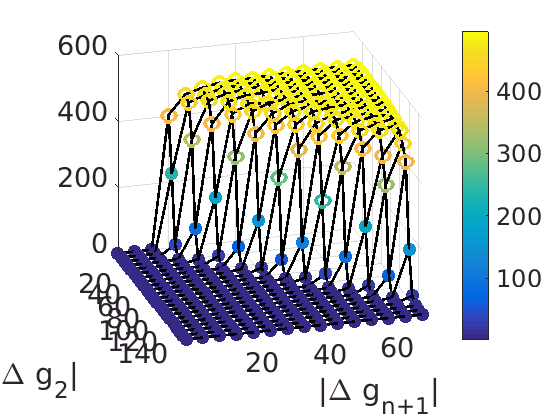

addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
for p = 1:length(paramset)
    load(paramset{p})
    f = figure();
    hold on
    set(gca,'fontsize',20)
    accinds = find(mouts(:,6)==0);
    naccinds = find(mouts(:,6)~=0);
    eminds = {naccinds,accinds};
    f = errorMesh(abs(mouts(:,1)),abs(mouts(:,2)),mouts(:,5),zeros(size(mouts(:,5))),[0 0 0],f,0,eminds);
    xlabel('|\Delta g_2|')
    ylabel('|\Delta g_{n+1}|')
    xlim([min(abs(mouts(:,1))) max(abs(mouts(:,1)))]);
    ylim([min(abs(mouts(:,2))) max(abs(mouts(:,2)))]);
    colorbar
    view([73.9 24.4])
end

Open circles represent a predicted distribution for which $\frac{f_{1000}}{f_k^*} > 0.1$, where $f_{1000}$ is the mass fraction of 1000-mers and $f_k^*$ is the maximum mass fraction in this system. Open circles, then, denote situations in which the mass moment of the system is likely underestimated due to a finite size effect.

This shows us that in general increasing the (magnitude of) the free energy of oligomerization increases the size of the resulting aggregates formed, while increasing the (magnitude of) the free energy of dimerization requires the free energy of oligomerization to increase in order to reach the same sizes, as might be expected.  The dotted red line is the line of equality, but it should be noted that the boundary of the region does not quite seem to follow it--for a sufficiently low dimerization free energy, the model predicts that large aggregate formation becomes favorable even if dimerization is more favorable than oligomerization.

In order to quantify this to a slightly greater extent, we fit a line to the boundary between the closed and open circles; that is we choose for each $|\Delta g_2|$ the $|\Delta g_{n+1}|$ corresponding to the  the maximum for which we expect a reasonably accurate estimate.

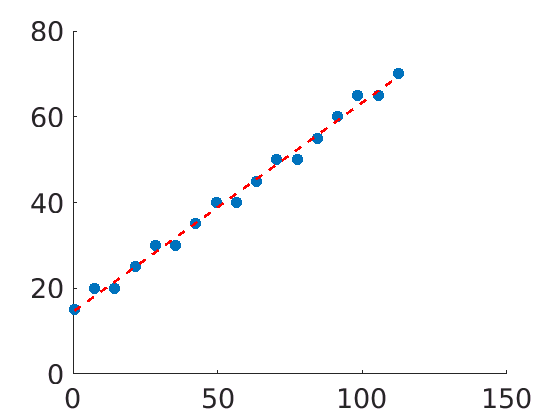

M2 = reshape(mouts(:,1),[15 length(mouts(:,1))/15]);
Mn = reshape(mouts(:,2),[15 length(mouts(:,2))/15]);
mu2 = reshape(mouts(:,5),[15 length(mouts(:,5))/15]);
flags = reshape(mouts(:,6),[15 length(mouts(:,6))/15]);
x = [];
y = [];
for c = 1:17
   ind = min(find(flags(:,c)==1))-1;
   x(c) = M2(ind,c);
   y(c) = Mn(ind,c);
end


figure()
hold on
set(gca,'fontsize',20)
plot(abs(x),abs(y),'.','markersize',30)
[f,gf] = fit(abs(x)',abs(y)','poly1');
plot(abs(x),f(abs(x)),'r--','linewidth',2)

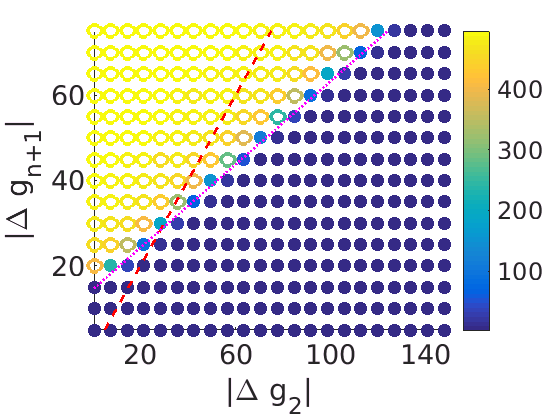


figure()
hold on
set(gca,'fontsize',20)
scatter(abs(mouts(accinds,1)),abs(mouts(accinds,2)),100,mouts(accinds,5),'filled')
scatter(abs(mouts(naccinds,1)),abs(mouts(naccinds,2)),100,mouts(naccinds,5),'linewidth',3)
plot(0:80,0:80,'r--','linewidth',2)
plot(0:150,f(0:150),'m:','linewidth',2)
xlabel('|\Delta g_2|')
ylabel('|\Delta g_{n+1}|')
xlim([min(abs(mouts(:,1))) max(abs(mouts(:,1)))]);
ylim([min(abs(mouts(:,2))) max(abs(mouts(:,2)))]);
colorbar

For dimerization magnitudes smaller than the intersection point, in order to see appreciable aggregation, the oligomerization magnitude must always be greater.

For dimerization magnitudes greater than the intersection point, there are some points for which there is still appreciable aggregation even if the (magnitude of) the oligomerization energy is less than the (magnitude of) the dimerization energy.

The intersection occurs at $x = y = \frac{p_2}{1-p_1}$ for a fit of the form $y = p_1 x + p_2$.

dgequal = f.p2/(1-f.p1);
fprintf('Crossover point is %f.\n',dgequal);

Crossover point is 28.270021.


## Compare to Bryce's predictions

predLoc = '/home/rachael/coarsegraining/idealGasModel/';
predData = [predLoc 'predictions.csv'];
predSafe = [predLoc 'predictions_safe.csv'];
predictions = importdata(predData)

predictions =         data: [9800x2 double]
    textdata: {9801x3 cell}


predictions_safe = importdata(predSafe)

predictions_safe =         data: [250x2 double]
    textdata: {251x3 cell}


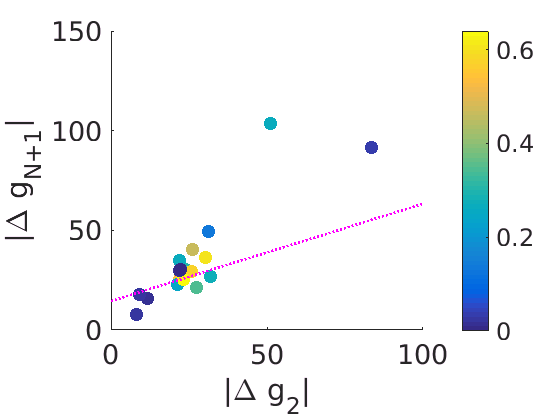

df2 = [-22.3 -11.8 -24 -8.1 -22.1 -21.8 -9 -27.3 -21.3 -25.8 -23.2 -21.8 -32 -22.2 -51.2 -30.4 -26.1 -83.4 -31.2];
sdf2 = [1.6 2.4 3.2 2.1 2.8 2.8 2.1 3 2.3 2.1 2 2.3 3.8 7.1 5.3 2.6 4.6 9.2 3.6];
df3 = [-25.5 -15.9 -30.6 -7.6 -25.3 -34.9 -17.8 -21.2 -22.8 -29.1 -25.4 -30.1 -27 -30.5 -103.5 -36.5 -40.3 -91.8 -49.6];
sdf3 = [3.2 6 3.9 1.9 3.2 4 3.6 2.9 3.3 5.2 3.2 4.9 4.6 3.9 38.5 7.9 6.8 28.9 4.2];
dfn = df3;
sdfn = sdf3;
align = [0.584 0.016 0.303 0.021 0.537 0.268 0.02 0.348 0.245 0.579 0.64 0.016 0.272 0 0.269 0.6 0.468 0.037 0.139];
salign = [0.039 0.007 0.039 0.016 0.042 0.042 0.006 0.033 0.014 0.048 0.072 0.005 0.048 0 0.021 0.085 0.047 0.01 0.02];
fig = figure();
hold on
set(gca,'fontsize',20)
scatter(-df2,-dfn,100,align,'filled')
xlabel('|\Delta g_2|')
ylabel('|\Delta g_{N+1}|')
colorbar
caxis([min(align) max(align)])
plot(0:100,f(0:100),'m:','linewidth',2)

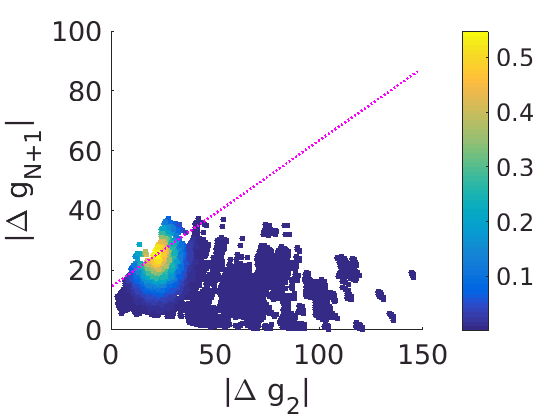

%plot(0:100,0:100,'r--','linewidth',2)

predictions = importdata('predictions.csv');
figure()
hold on
set(gca,'fontsize',20)
scatter(-predictions.data(:,1),-predictions.data(:,2),20,predictions.data(:,3),'filled')
xlabel('|\Delta g_2|')
ylabel('|\Delta g_{N+1}|')
colorbar
%caxis([min(align) max(align)])
plot(min(abs(mouts(:,1))):max(abs(mouts(:,1))),f(min(abs(mouts(:,1))):max(abs(mouts(:,1)))),'m:','linewidth',2)

plot(min(abs(mouts(:,1))):max(abs(mouts(:,1))),min(abs(mouts(:,1))):max(abs(mouts(:,1))),'r--','linewidth',2)

Here I've plotted Bryce's predictions, using $\Delta g_2 \equiv \Delta F_2 $ and $\Delta g_{N+1} \equiv \Delta F_3$, colored by the measured alignment value.  

I think it's really interesting that a lot of the better alignment values are falling quite close to the crossover point mentioned above--since the above is a pretty handwavey prediction, the line may also be off (not to mention the definition of "appreciable aggregation") but assuming that it's not completely off, what this suggests is that "good alignment" tends to occur for the slowest possible "appreciable" growth -- maybe when optical & contact clusters are growing at the same rate.

Basically, we see from the previous analysis that there's an abrupt divide between "lots of growth" and "no growth" for what are essentially contact clusters (in the sense that they're just any form of aggregate) and we see that if we're relatively far away from the line we may not get as good growth.  To do this analysis properly I'd really like to take the full table of values from the model and look at the predicted alignments, since right now there's not that many off-line data points to look at, but it's at least suggestive that what we want really is "the slowest growth you can get while getting growth" to get the most nicely aligned aggregate (which ties in pretty nicely with the fact we've been targeting large values of optical/cluster growth).

## Adding further oligomerization energies

From the previous analysis, we observe that there is very little change as we go from 500 to 2000 bins; we still capture the sharp separation between "almost no growth" and "lots of growth" for just 500 bins each; therefore we choose to employ only 500 bins as we go to a somewhat more in-depth model, wherein we now allow some of the higher order oligomerization free energies to change independently.  We begin by simply going to additional trimerization energies.

Two interesting questions:

(1) Allow the oligomerization energy to change at some point -- what do the distributions look like as a function of *when* that oligomerization energy changes?

(2) What do the distributions look like as function *of* the changing free energies with the division set in a particular place?

dg1plus1 = -14.5;
dg1plusn = -25*ones(1,k_max);
k_max = 500;
ks = 1:500;
dg_vec = zeros(1,k_max);
dg_vec(2:end) = dg1plus1 + (ks(2:end)-2).*dg1plusn(2:end);
figure()
hold on
set(gca,'fontsize',20)
plot(1:k_max,dg_vec,'linewidth',2)
xlabel('N')
ylabel('\Delta g_N')

Let the addition of a monomer become less favorable at some point

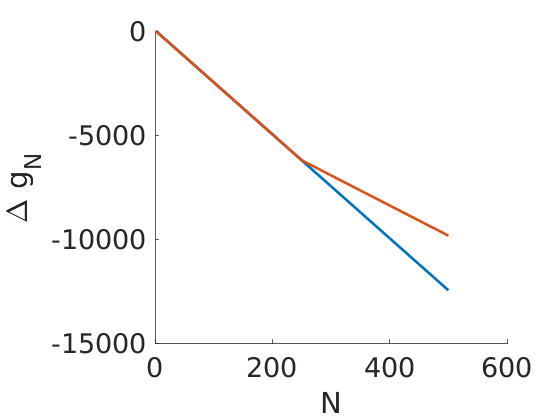

dg_vec = zeros(1,k_max);
kmid = 250;
dg1plusn1 = -25;
dg1plusn2 = -14.5;
dg_vec = zeros(1,k_max);
dg_vec(2:kmid) = dg1plus1 + (ks(2:kmid)-2)*dg1plusn1;
dg_vec((kmid+1):k_max) = dg1plus1 + (ks(kmid)-2)*dg1plusn1 + (ks((kmid+1):end)-kmid)*dg1plusn2;
plot(1:k_max,dg_vec,'linewidth',2)

## Parameter Scan : changing where kmid is

tic
k_max = 500;
dg1plus1s = -1*(0.5:7:40.5);%dimerization
dg1plusns1 = 
dgnplus1 = -25;%oligomerization
kmids = 20:40:k_max;
g1l = length(dg1plus1s);
kml = length(kmids);
mouts = zeros(g1l*kml,6);
outputs = {};
douts = zeros(g1l*kml,k_max);
ind = 1;
A = [];
b = [];
Aeq = ones(1,k_max);
beq = [1];
lb = zeros(1,k_max);
ub = ones(1,k_max);
nonlcon = [];
x0 = ones(1,k_max);
dg_vec = zeros(1,k_max);
for dg1plus1 = dg1plus1s
   for kmid = kmids
       dg_vec(2:kmid) = dg1plus1 + (ks(2:kmid)-2)*dg1plusn1;
       dg_vec((kmid+1):k_max) = dg1plus1 + (ks(kmid)-2)*dg1plusn1 + (ks((kmid+1):end)-kmid)*dg1plusn2;
       [x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
       
       douts(ind,:) = x;
       mouts(ind,1) = dg1plus1;
       mouts(ind,2) = kmid;
       mouts(ind,3) = fval;
       mouts(ind,4) = exitflag;
       outputs{ind} = output;
       
       mu2 = sum((1:k_max).*x);%mu2 = sum_k k f_k
       mouts(ind,5) = mu2;
     
       mouts(ind,6) = (x(end)/max(x) > 0.1);
       
       figure()
       bar([1:1:k_max],x);
       xlabel('no. molecules per aggregate','fontsize',fsize);
       ylabel('mass fraction','fontsize',fsize);
       %xlim([0 find(x~=0)])
       set(gca,'fontsize',fsize);
       set(gcf,'color','w');
       savefig(['statMechModel_oligopeptides_500_kmids_' num2str(ind)]);
       saveas(gcf,['statMechModel_oligopeptides_500_kmids_' num2str(ind)],'pdf');
       ind = ind + 1;
       close();
   end
end
toc

Elapsed time is 1478.208594 seconds.


save('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins_kmids.mat','mouts','douts');

## Visualize the outcome

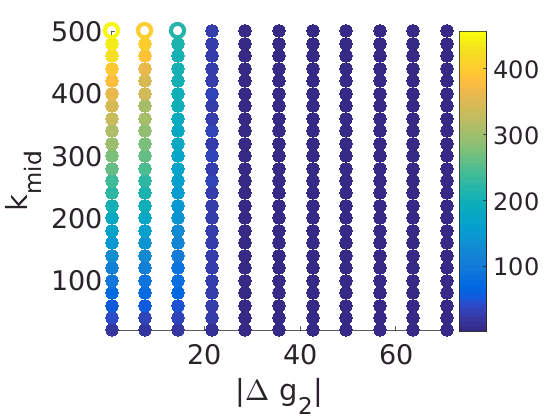

load('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins_kmids.mat');
accinds = find(mouts(:,6)==0);
naccinds = find(mouts(:,6)~=0);
figure()
hold on
set(gca,'fontsize',20)
scatter(abs(mouts(accinds,1)),abs(mouts(accinds,2)),100,mouts(accinds,5),'filled')
scatter(abs(mouts(naccinds,1)),abs(mouts(naccinds,2)),100,mouts(naccinds,5),'linewidth',3)

xlabel('|\Delta g_2|')
ylabel('k_{mid}')
xlim([min(abs(mouts(:,1))) max(abs(mouts(:,1)))]);
ylim([min(abs(mouts(:,2))) max(abs(mouts(:,2)))]);
colorbar

## Parameter scan, changing kmid, dimerization and the two oligomerization energies

## Parameter Scan : changing where kmid is

tic
k_max = 500;
dg1plus1s = -1*(0.5:7:40.5);%dimerization
dg1plusns1 = -1*(5:5:45);%oligomerization 1
dg1plusns2 = -1*(5:5:45);%oligomerization 2

kmids = 20:40:k_max;
g1l = length(dg1plus1s);
kml = length(kmids);
dgn1 = length(dg1plusns1);
dgn2 = length(dg1plusns2);
mouts = zeros(g1l*kml*dgn1*dgn2,8);
outputs = {};
douts = zeros(g1l*kml*dgn1*dgn2,k_max);
ind = 1;
A = [];
b = [];
Aeq = ones(1,k_max);
beq = [1];
lb = zeros(1,k_max);
ub = ones(1,k_max);
nonlcon = [];
x0 = ones(1,k_max);
dg_vec = zeros(1,k_max);
for dg1plus1 = dg1plus1s
   for kmid = kmids
       for dg1plusn1 = dg1plusns1
           for dg1plusn2 = dg1plusns2
               dg_vec(2:kmid) = dg1plus1 + (ks(2:kmid)-2)*dg1plusn1;
               dg_vec((kmid+1):k_max) = dg1plus1 + (ks(kmid)-2)*dg1plusn1 + (ks((kmid+1):end)-kmid)*dg1plusn2;
               [x,fval,exitflag,output] = fmincon_runnested(x0,A,b,Aeq,beq,lb,ub,nonlcon,options_fmincon,T,dg_vec,T_ref,rho,Lambda_1);
               
               douts(ind,:) = x;
               mouts(ind,1) = dg1plus1;
               mouts(ind,2) = kmid;
               mouts(ind,3) = dg1plusn1;
               mouts(ind,4) = dg1plusn2;
               mouts(ind,5) = fval;
               mouts(ind,6) = exitflag;
               outputs{ind} = output;
               
               mu2 = sum((1:k_max).*x);%mu2 = sum_k k f_k
               mouts(ind,7) = mu2;
               
               mouts(ind,8) = (x(end)/max(x) > 0.1);
               
               figure()
               bar([1:1:k_max],x);
               xlabel('no. molecules per aggregate','fontsize',fsize);
               ylabel('mass fraction','fontsize',fsize);
               %xlim([0 find(x~=0)])
               set(gca,'fontsize',fsize);
               set(gcf,'color','w');
               savefig(['statMechModel_oligopeptides_500_kmids_' num2str(ind)]);
               saveas(gcf,['statMechModel_oligopeptides_500_kmids_' num2str(ind)],'pdf');
               ind = ind + 1;
               close();
           end
       end
   end
end
toc
save('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins_kmids_2oligomerizations.mat','mouts','douts');

## Visualize previous 

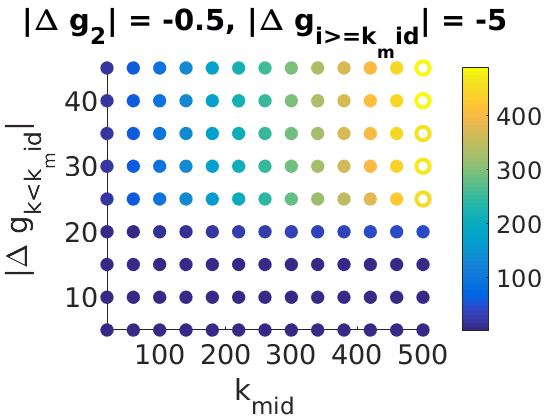

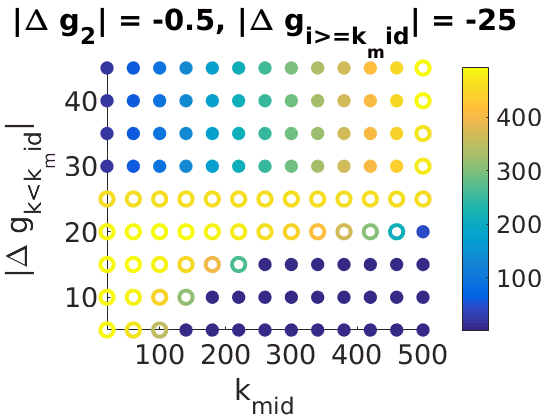

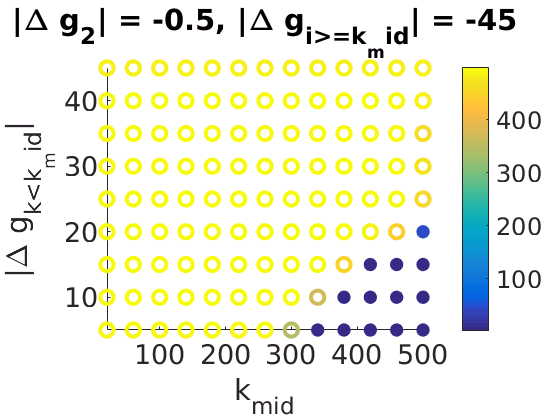

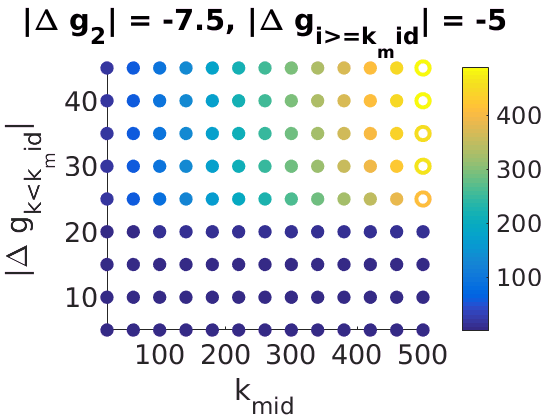

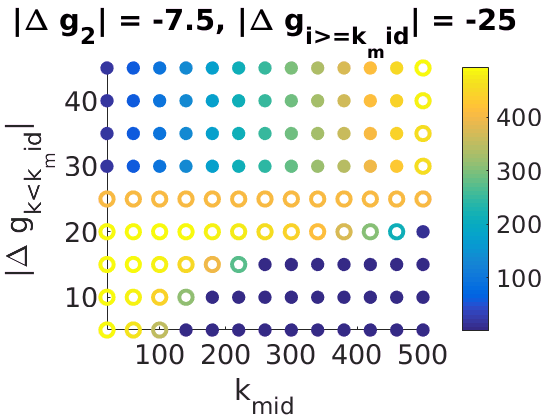

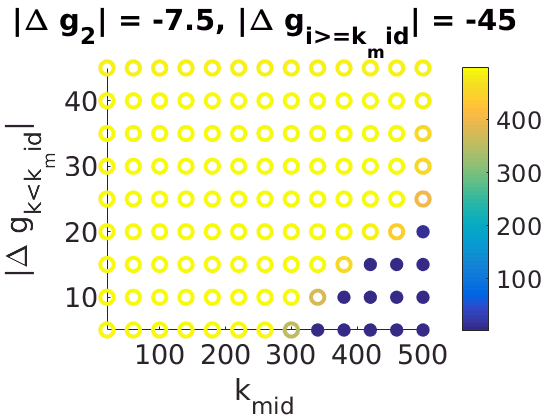

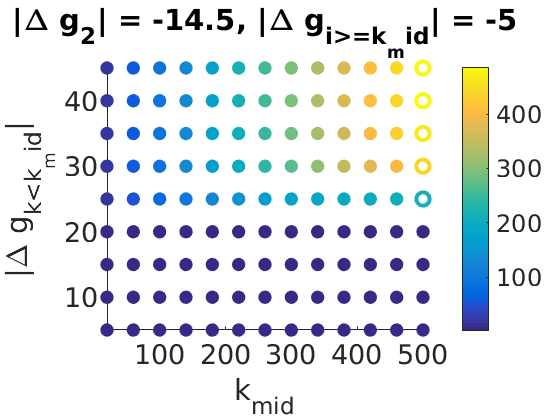

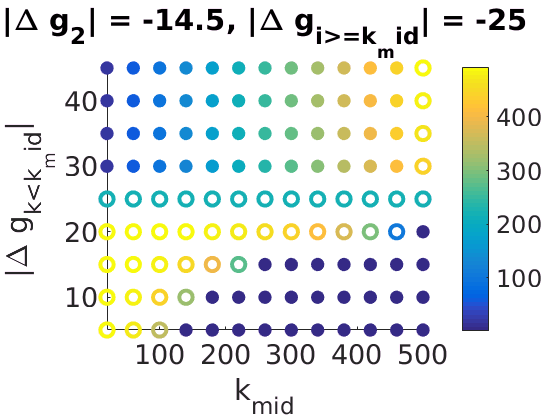

load('/home/rachael/Analysis_and_run_code/lab_notebook/CG_idealgas/parameterscan_500bins_kmids_2oligomerizations.mat');
for j = 1:length(dg1plus1s)
for i = [1 5 9]
accinds = find(mouts(:,8)==0 & mouts(:,1)==dg1plus1s(j) & mouts(:,4) == dg1plusns2(i));
naccinds = find(mouts(:,8)~=0 & mouts(:,1)==dg1plus1s(j) & mouts(:,4) == dg1plusns2(i));
figure()
hold on
set(gca,'fontsize',20)
scatter(abs(mouts(accinds,2)),abs(mouts(accinds,3)),100,mouts(accinds,7),'filled')
scatter(abs(mouts(naccinds,2)),abs(mouts(naccinds,3)),100,mouts(naccinds,7),'linewidth',3)
title(['|\Delta g_2| = ' num2str(dg1plus1s(j)) ', |\Delta g_{i>=k_mid}| = ' num2str(dg1plusns2(i))])
xlabel('k_{mid}')
ylabel('|\Delta g_{k<k_mid}|')
xlim([min(abs(mouts(:,2))) max(abs(mouts(:,2)))]);
ylim([min(abs(mouts(:,3))) max(abs(mouts(:,3)))]);
colorbar
end
end

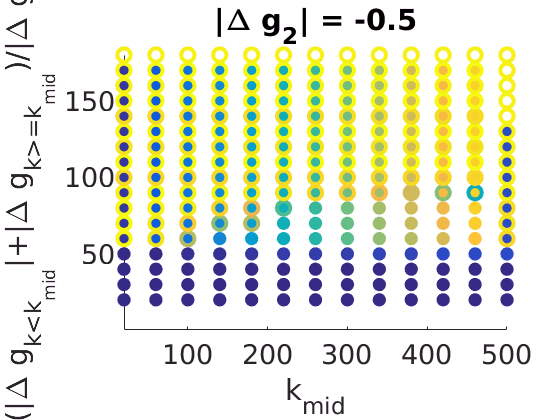

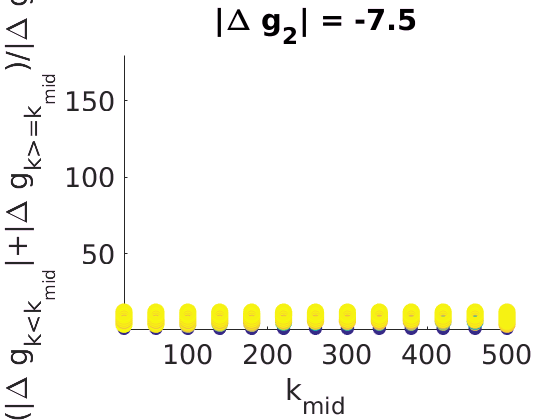

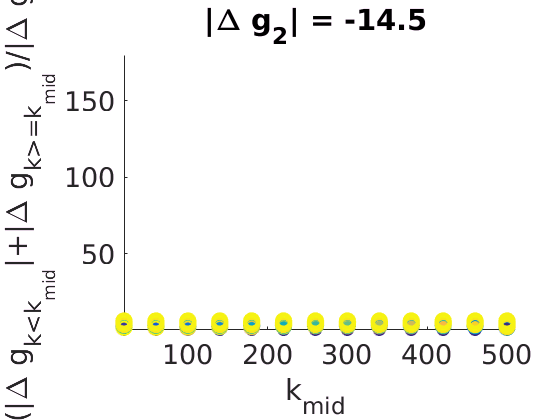

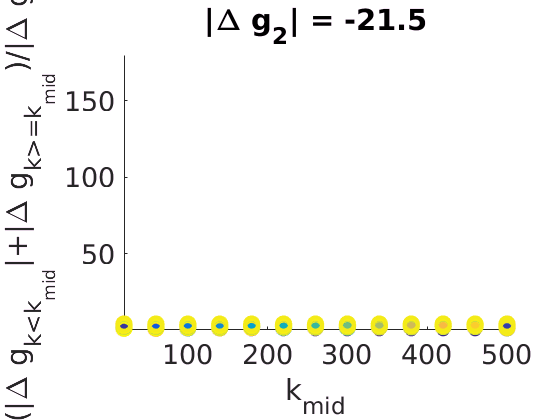

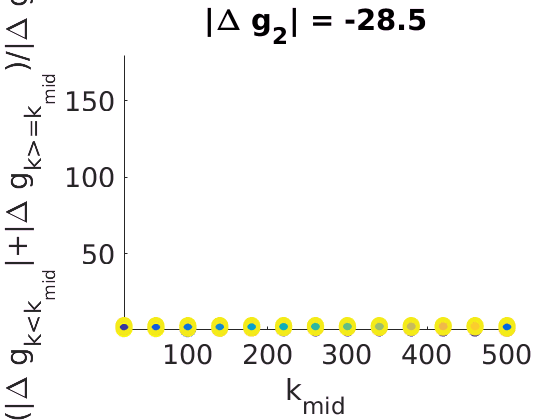

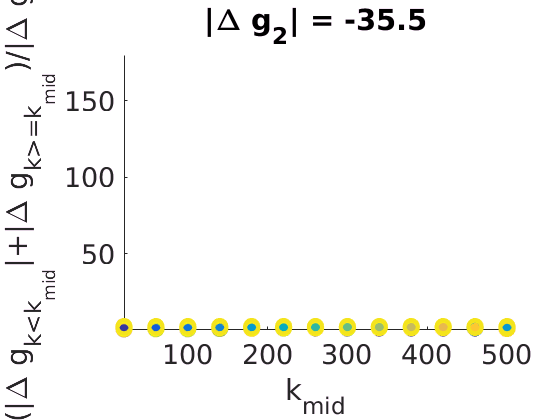

%consider total oligomerization energy/dimerization energy
j = 1;
for j = 1:length(dg1plus1s)
accinds = find(mouts(:,8)==0 & mouts(:,1)==dg1plus1s(j) );
naccinds = find(mouts(:,8)~=0 & mouts(:,1)==dg1plus1s(j));
figure()
hold on
set(gca,'fontsize',20)
scatter(abs(mouts(accinds,2)),(abs(mouts(accinds,3))+abs(mouts(accinds,4)))./(abs(mouts(accinds,1))),100,mouts(accinds,7),'filled')
scatter(abs(mouts(naccinds,2)),(abs(mouts(naccinds,3))+abs(mouts(naccinds,4)))./(abs(mouts(naccinds,1))),100,mouts(naccinds,7),'linewidth',3)
title(['|\Delta g_2| = ' num2str(dg1plus1s(j))])
xlabel('k_{mid}')
ylabel('(|\Delta g_{k<k_{mid}}|+|\Delta g_{k>=k_{mid}})/|\Delta g_2|')
%xlim([min(abs(mouts(:,2))) max(abs(mouts(:,2)))]);
%ylim([min((abs(mouts(:,3))+abs(mouts(:,4)))./(abs(mouts(:,1)))) max((abs(mouts(:,3))+abs(mouts(:,4)))./(abs(mouts(:,1))))]);
end